# Relay Orbit

To find the ideal Orbit for a satellite to travel in around a body of radius, r, such that the communication is continuous on any point on that body with a signal strength of at least 80%

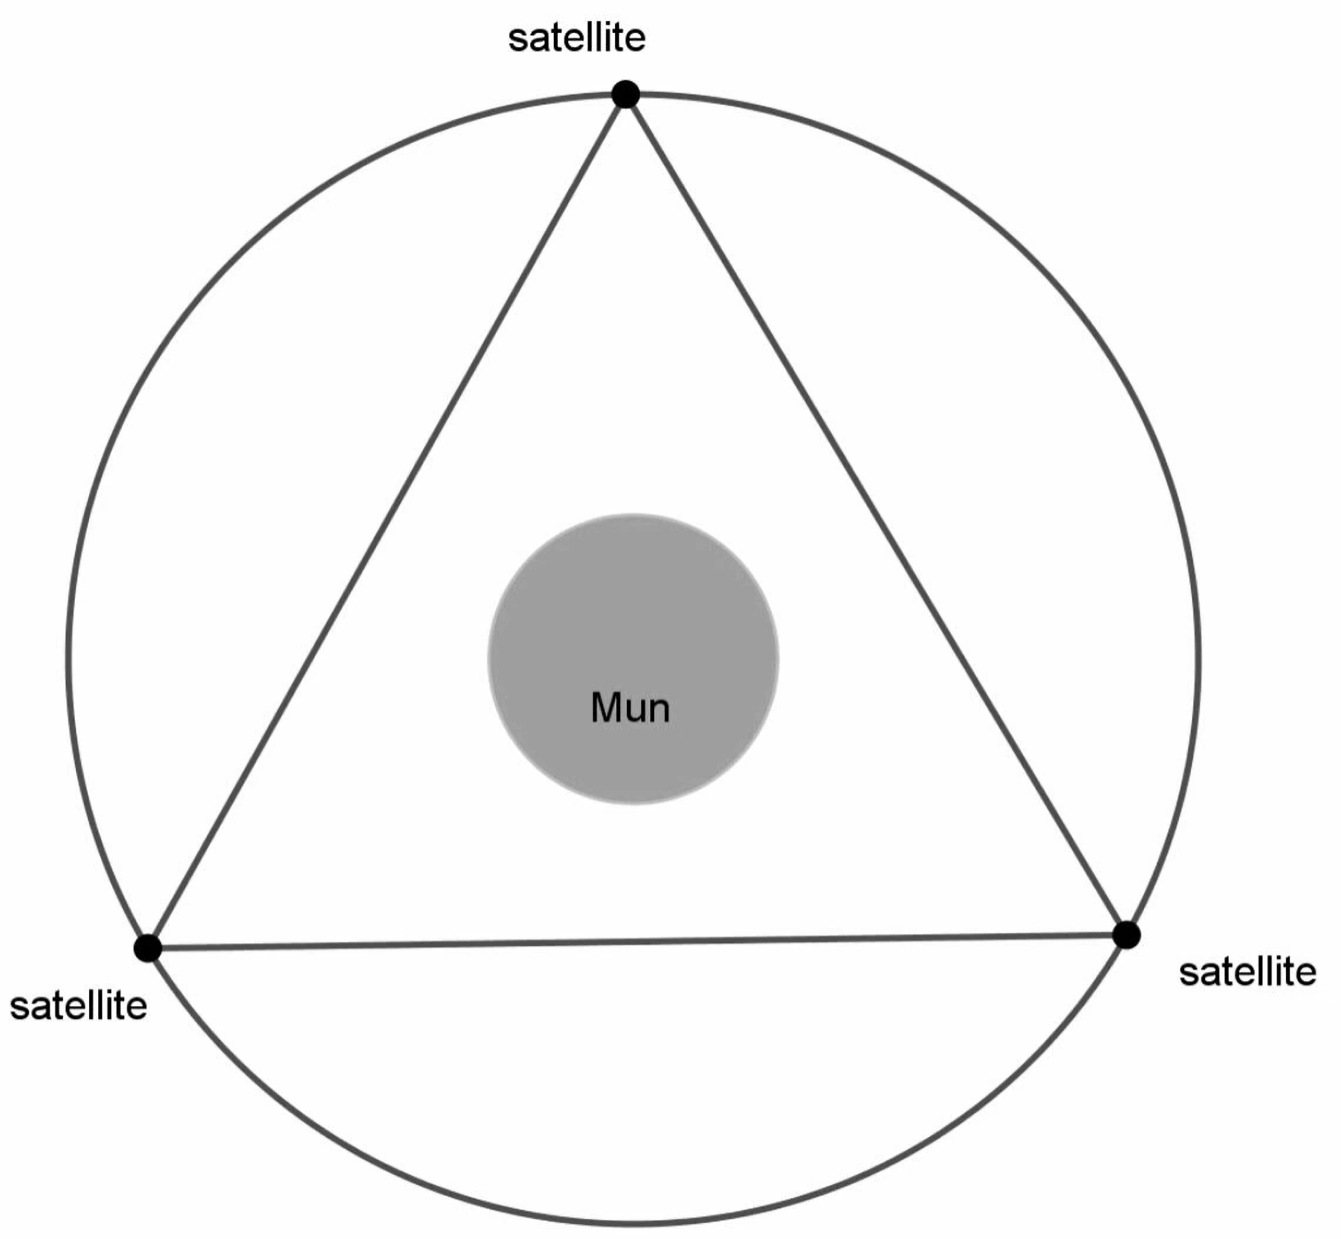

These 3 points are the vertices of an equilateral triangle. Therfore, if the radius is too small the vertices will pass throught the body and interrupt comms.

Too far out and communication to and from the body will lose strength.

Making the vertices a tangent to the circle would likely also cause problems as if the orbit changed slightly then the comms would be interrupted as the body intercepts the vertices.

Thus the altitude of the minimum allowable orbit would be r, the radius of the body. (see below)

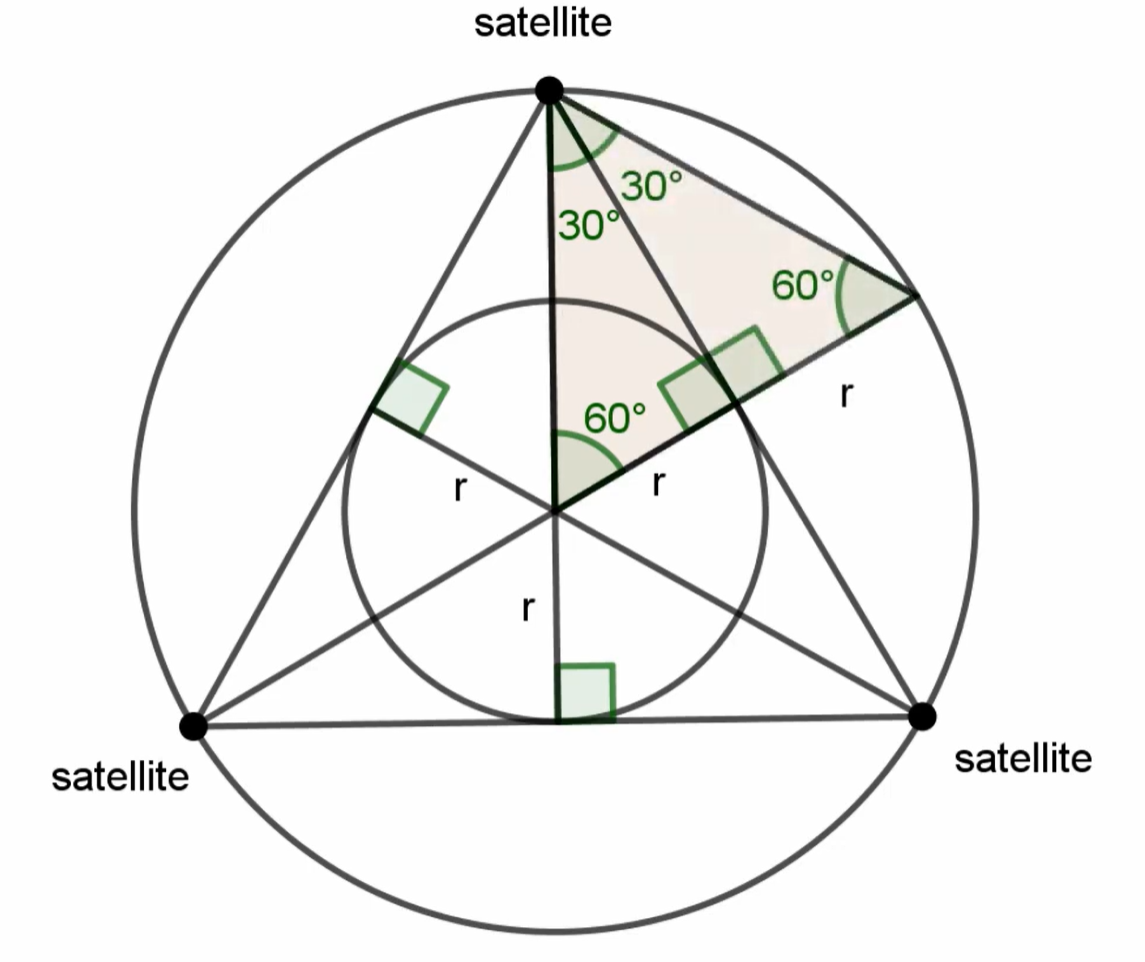

The upper bound would be the sphere of influence of the body (for now).

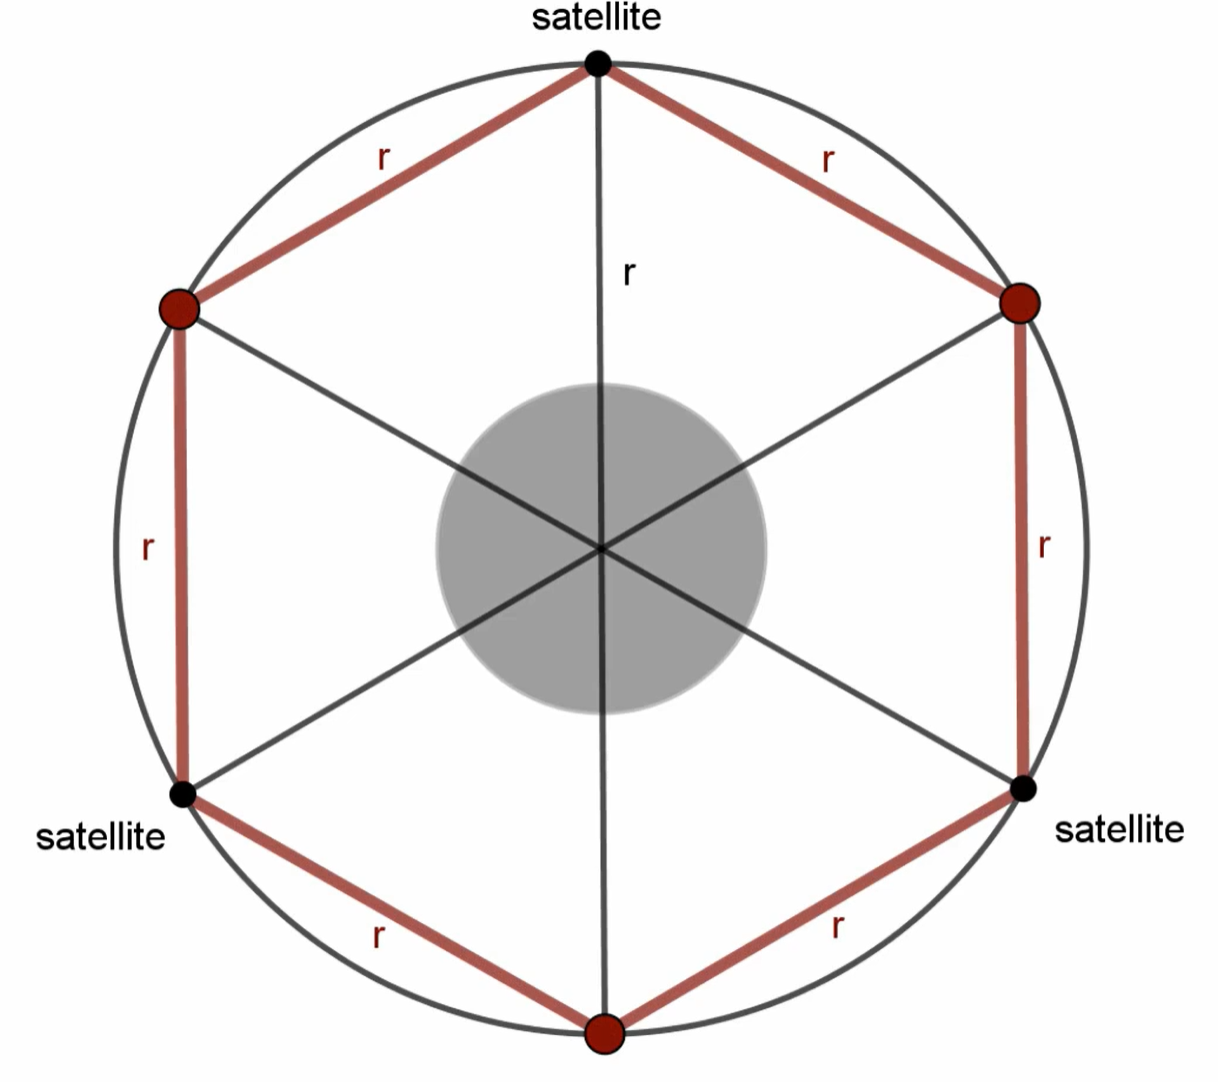

As you can see above, the maximum distance from any satellite that isn't in the centre of the body is r, the radius of the orbit from the centre of the body, or 2 x radius of the radius of the body itself also.

**From here on, the radius of the orbit from centre will be d, and radius of the body/orbit from surface will be r.**

## Walkthrough

The first thing to know is the power range of each antenna.

For this example we will be using the **HG-5 **and **Communotron 16**

**HG5_power_km = 5000;**

**Comm16_power_km = 500;**

We then use these to calculate the range of comms between the two antenna.

**range = sqrt(HG5_power_km*Comm16_power_km);**

Using the given signal strength formulae, signal = -2x^3 + 3x^2 and the fact that we want the signal strength to be at least 80%. We use this to calculate x.

**signal = 0.8;**

**x = roots of, -2x^3 + 3x^2 - 0.8**

We take the value where, 0 < x < 1, so that we get the correct distance.

**x = 0.71;**

We then use the equation to calculate the distance, which is d in this case, the max distance between each satellite.

**distance = range*(1-x);**

This gives an orbital distance above the surface of 258km.

We can also calculate the time period of the orbit.

**G = 6.67408e-11;**

**M = 9.7599e20;**

**T = sqrt((4 * pi^2 * (distance*1000)^3) / (G * M));**

**T_hours = datestr(seconds(T),'HH:MM:SS');**

## Evaluation

- Ensure that the orbit isn't too close to the minimum, any deviation from the ideal orbit could lead to communication issues

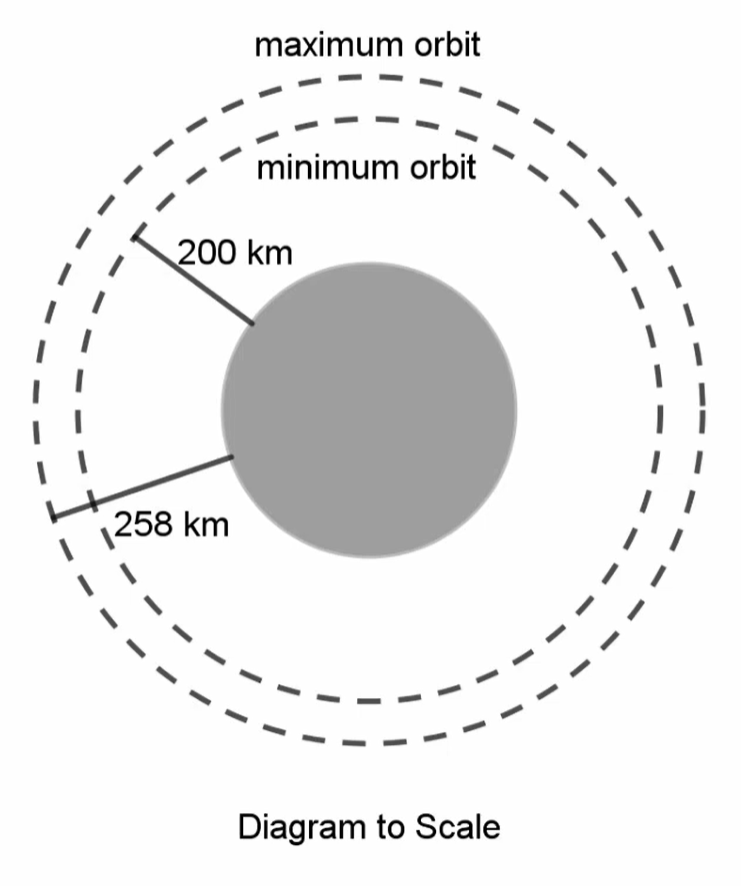As you can see here the distance of the orbit isn't much greater than the minimum

- Ensure that the time period is large enough to be divisible by 3 and still a great enough difference from the normal time period to allow phasing the satellites into place

# Calculations

power_range1 = 5000;
power_range2 = 500;
c = 0.75;

compatibility factor, c, is normally 0.75

This below is used if using more than one antenna on the satellite, change the number below depending on how many you are using.

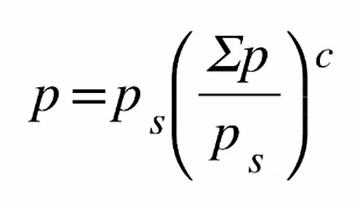

power_range1_combine = power_range1*(power_range1* 2 /power_range1)^c

power_range1_combine = 8.4090e+03

power_range2_combine = power_range2*(power_range2* 1 /power_range2)^c

power_range2_combine = 500

Evaluate the range

range = sqrt(power_range1_combine*power_range2_combine)

range = 2.0505e+03

Evaluate for x, changing the required signal strength as necessary

signal = 0.82;
x = [-2 3 0 -signal];
x = roots(x);
fprintf("x = %.2f ",x)

x = 1.23 x = 0.73 x = -0.46 

Use x where 0 < x < 1 to calculate distance

x = 0.73;
distance = range*(1-x);
fprintf("Max Distance = %.2f",distance)

Max Distance = 553.63

We can then change the distance below to get a time period of orbit that is divisible by 3

distance = 538.192

distance = 538.1920

distance_above_surface = distance - 200

distance_above_surface = 338.1920

Time period of orbit

G = 6.67408e-11;
M = 9.7599e20;
T = sqrt((4 * pi^2 * (distance*1000)^3) / (G * M));
fprintf("Time Period (s) = %.2f",T)

Time Period (s) = 9720.02

T_hours = datestr(seconds(T),'HH:MM:SS')

T_hours = '02:42:00'

Time period of Relay orbit

T_relay = T*4/3;
fprintf("Time Period Relay Orbit (s) = %.2f",T_relay)

Time Period Relay Orbit (s) = 12960.03

T_hours_relay = datestr(seconds(T_relay), 'HH:MM:SS')

T_hours_relay = '03:36:00'